%% ========================================================================
%  Admittance Matrix Analysis: Y(s) = I(s) / V(s)
%  - Load state-space model from .mat
%  - Extract 2x2 transfer matrix from voltage inputs (alpha/beta) to currents
%  - Plot Bode of each element
%  - Pole/zero analysis (minreal) + auto report (.txt)
%
%  Author: (your name)
%  Date  : (auto)
%% ========================================================================

clear; clc; close all;

%% ----------------------------- User Config ------------------------------
matFile = "iP01_iV01_iQ01_iX01__P-1000m_Q+0m_V+1000m_xi+5730md.mat";
tol     = 1e-8;   % numerical tolerance for minreal / filtering

% Which inputs correspond to v_alpha, v_beta?
voltageInputIdx = 1:2;

% Plot configs
figPosBode = [100, 100, 1200, 800];
figPosPZ   = [200, 120, 1100, 800];
%% ------------------------------------------------------------------------

%% 1) Load model
S = load(matFile);
assert(isfield(S, "sys"), "MAT文件中未找到变量 sys：%s", matFile);

sys = S.sys;  % expected: ss(A,B,C,D)
fprintf("Loaded model from: %s\n", matFile);

Loaded model from: iP01_iV01_iQ01_iX01__P-1000m_Q+0m_V+1000m_xi+5730md.mat


disp(sys);

  2×4 ss 数组 - 属性:

                A: [16×16 double]
                B: [16×4 double]
                C: [2×16 double]
                D: [2×4 double]
                E: []
          Offsets: []
           Scaled: 0
        StateName: {16×1 cell}
        StatePath: {16×1 cell}
        StateUnit: {16×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [4×1 double]
      OutputDelay: [2×1 double]
        InputName: {4×1 cell}
        InputUnit: {4×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {2×1 cell}
       OutputUnit: {2×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]




%% 2) Extract voltage -> current subsystem (2 outputs x 2 inputs)
% sys(:, voltageInputIdx) means: all outputs, selected voltage inputs
sys_v2i = sys(:, voltageInputIdx);

% Convert to transfer function matrix: Y(s) = I/V
Y = tf(sys_v2i);

% Name each element for clarity
Yaa = Y(1,1);  % v_alpha -> i_alpha
Yab = Y(1,2);  % v_beta  -> i_alpha
Yba = Y(2,1);  % v_alpha -> i_beta
Ybb = Y(2,2);  % v_beta  -> i_beta

fprintf("\nAdmittance matrix elements:\n");


Admittance matrix elements:


fprintf("  Yaa: v_alpha -> i_alpha\n");

  Yaa: v_alpha -> i_alpha


fprintf("  Yab: v_beta  -> i_alpha\n");

  Yab: v_beta  -> i_alpha


fprintf("  Yba: v_alpha -> i_beta\n");

  Yba: v_alpha -> i_beta


fprintf("  Ybb: v_beta  -> i_beta\n");

  Ybb: v_beta  -> i_beta


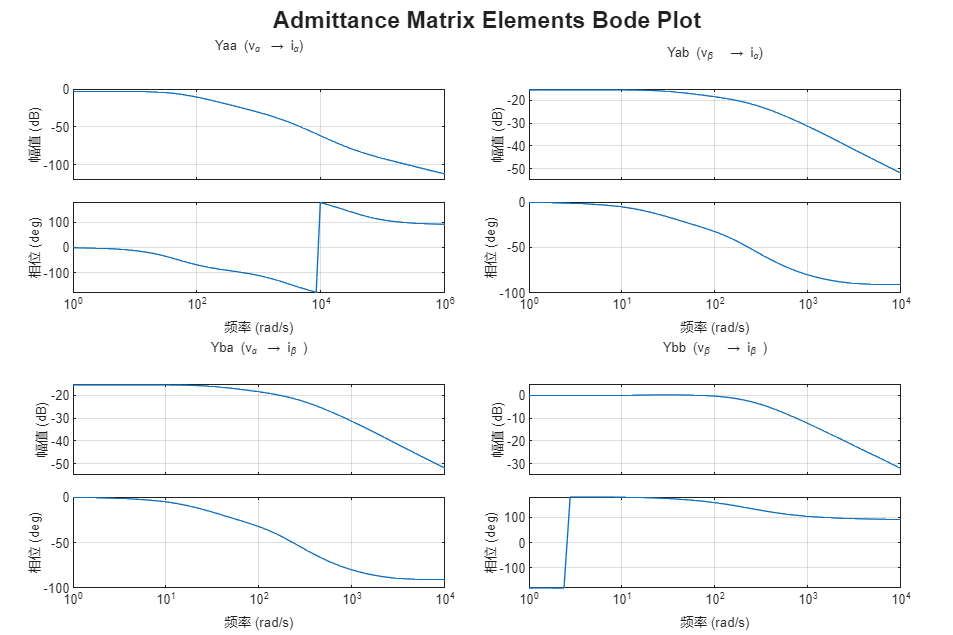


%% 3) Bode plots (4 subplots)
figure('Color','white','Position',figPosBode);
tlo = tiledlayout(2,2,'TileSpacing','compact','Padding','compact');
title(tlo, "Admittance Matrix Elements Bode Plot", "FontSize", 14, "FontWeight","bold");

opt = bodeoptions;
opt.Grid = "on";
opt.PhaseWrapping = "on";
opt.FreqUnits = "rad/s";     % 可按需改为 'Hz'
opt.MagUnits  = "dB";
opt.Title.String = "";       % 我们用每个tile自己的title

plotBodeTile(tlo, 1, Yaa, "Yaa (v_\alpha \rightarrow i_\alpha)", opt);
plotBodeTile(tlo, 2, Yab, "Yab (v_\beta  \rightarrow i_\alpha)", opt);
plotBodeTile(tlo, 3, Yba, "Yba (v_\alpha \rightarrow i_\beta )", opt);
plotBodeTile(tlo, 4, Ybb, "Ybb (v_\beta  \rightarrow i_\beta )", opt);

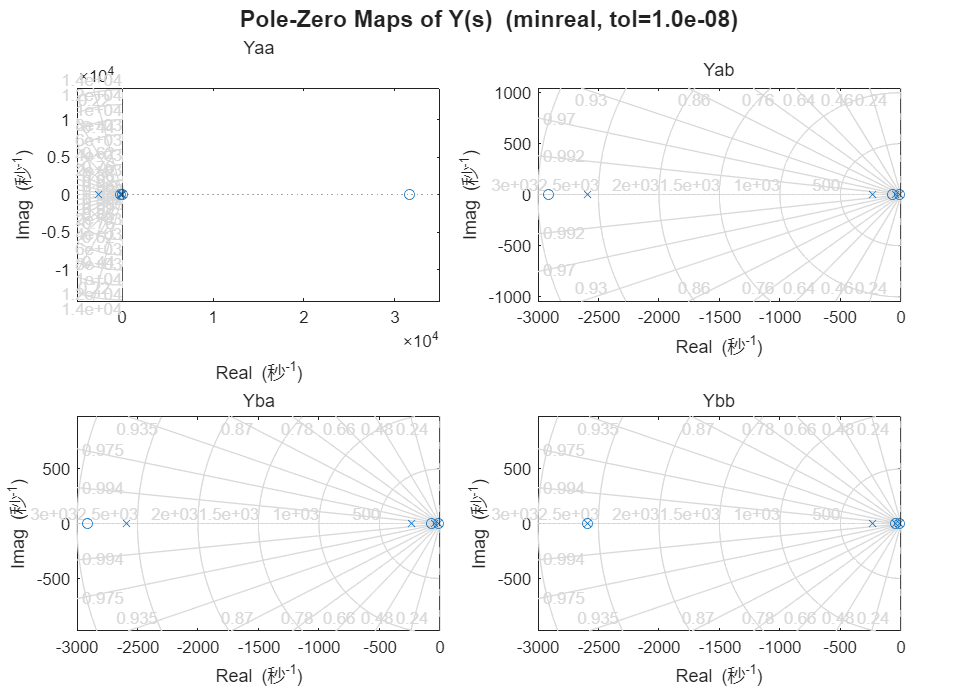


========== Yaa ==========


Gain k = -2.49168


Zeros: 5, Poles: 6


RHP Zeros: 1, RHP Poles: 0


Stability (CT): Stable (all poles in LHP)


Pole closest to imag-axis (max Re): -10.1772+0j



-- Zeros z --


  1: 31670.3063604+0j
  2: -250.530553294+0j
  3: -15.0020432544+0j
  4: -13.5396957355+0j
  5: -9.99831009672+0j



-- Poles p --


  1: -2591.73985378+0j
  2: -236.467484048+0j
  3: -46.5481367344+0j
  4: -14.8708724615+0j
  5: -13.532515952+0j
  6: -10.177170878+0j



========== Yab ==========


Gain k = 24.8337


Zeros: 5, Poles: 6


RHP Zeros: 0, RHP Poles: 0


Stability (CT): Stable (all poles in LHP)


Pole closest to imag-axis (max Re): -10.1772+0j



-- Zeros z --


  1: -2911.79552353+0j
  2: -69.022618669+0j
  3: -14.9209223808+0j
  4: -13.1687399316+0j
  5: -10.0853721964+0j



-- Poles p --


  1: -2591.73985378+0j
  2: -236.467484048+0j
  3: -46.5481367344+0j
  4: -14.8708724615+0j
  5: -13.532515952+0j
  6: -10.177170878+0j



========== Yba ==========


Gain k = 24.8337


Zeros: 5, Poles: 6


RHP Zeros: 0, RHP Poles: 0


Stability (CT): Stable (all poles in LHP)


Pole closest to imag-axis (max Re): -10.1772+0j



-- Zeros z --


  1: -2911.79552353+0j
  2: -69.022618669+0j
  3: -14.9209223808+0j
  4: -13.1687399316+0j
  5: -10.0853721964+0j



-- Poles p --


  1: -2591.73985378+0j
  2: -236.467484048+0j
  3: -46.5481367344+0j
  4: -14.8708724615+0j
  5: -13.532515952+0j
  6: -10.177170878+0j



========== Ybb ==========


Gain k = -247.508


Zeros: 5, Poles: 6


RHP Zeros: 0, RHP Poles: 0


Stability (CT): Stable (all poles in LHP)


Pole closest to imag-axis (max Re): -10.1772+0j



-- Zeros z --


  1: -2588.547019+0j
  2: -46.295712127+0j
  3: -14.8700560607+0j
  4: -12.7925578929+0j
  5: -10.1791299993+0j



-- Poles p --


  1: -2591.73985378+0j
  2: -236.467484048+0j
  3: -46.5481367344+0j
  4: -14.8708724615+0j
  5: -13.532515952+0j
  6: -10.177170878+0j



%% 4) Pole-Zero analysis + report
ts = datestr(now,'yyyymmdd_HHMMSS');
reportFile = "Y_zpk_report_" + ts + ".txt";

fid = fopen(reportFile,'w');
assert(fid >= 0, "无法创建报告文件：%s", reportFile);

fprintf(fid, "导纳矩阵 Y(s) 元素零极点分析报告\n");
fprintf(fid, "生成时间: %s\n", datestr(now,'yyyy-mm-dd HH:MM:SS'));
fprintf(fid, "MAT文件: %s\n", matFile);
fprintf(fid, "过滤阈值 tol = %.1e\n\n", tol);

names = {"Yaa","Yab","Yba","Ybb"};
tfs   = {Yaa,  Yab,  Yba,  Ybb };

% pole-zero map figure
hfig = figure('Color','white','Position',figPosPZ,'Name',"Pole-Zero Maps of Y(s)");
tlo2 = tiledlayout(hfig, 2, 2, 'TileSpacing','compact','Padding','compact');
title(tlo2, sprintf("Pole-Zero Maps of Y(s)  (minreal, tol=%.1e)", tol), ...
    'FontSize', 14, 'FontWeight','bold');

for k = 1:numel(tfs)
    G = minreal(tfs{k}, tol);        % remove near pole-zero cancellations
    [z, p, k_gain] = zpkdata(G,'v'); % vectors

    % Filter tiny numerical noise close to 0
    z = cleanVec(z, tol);
    p = cleanVec(p, tol);

    numRHPz = sum(real(z) > tol);
    numRHPp = sum(real(p) > tol);

    stableFlag = isStableCT(p, tol);

    p_near = nearestToImagAxis(p);

    % ---- Plot pole-zero map
    nexttile(tlo2, k);
    h = pzplot(G);
    grid on; axis equal;
    xline(0,'--'); % imaginary axis
    title(names{k}, 'Interpreter','none');
    xlabel('Real'); ylabel('Imag');

    % Set marker styles (robust)
    stylePoleZeroMarkers(h);

    % ---- Console output
    fprintf("\n========== %s ==========\n", names{k});
    fprintf("Gain k = %.6g\n", k_gain);
    fprintf("Zeros: %d, Poles: %d\n", numel(z), numel(p));
    fprintf("RHP Zeros: %d, RHP Poles: %d\n", numRHPz, numRHPp);
    fprintf("Stability (CT): %s\n", ternary(stableFlag, "Stable (all poles in LHP)", "Unstable (RHP/imag-axis poles exist)"));
    if ~isempty(p_near)
        fprintf("Pole closest to imag-axis (max Re): %.6g%+.6gj\n", real(p_near), imag(p_near));
    end
        % ---- Console: print explicit zeros/poles
    fprintf("\n-- Zeros z --\n");
    writeComplexList(1, z);     % 1 == command window

    fprintf("\n-- Poles p --\n");
    writeComplexList(1, p);

    fprintf("\n");


    % ---- Report file
    fprintf(fid, "========== %s ==========\n", names{k});
    fprintf(fid, "minreal后传递函数(简化表示):\n%s\n", evalc('disp(G)'));
    fprintf(fid, "增益 k = %.12g\n", k_gain);
    fprintf(fid, "零点数量: %d, 极点数量: %d\n", numel(z), numel(p));
    fprintf(fid, "RHP零点: %d, RHP极点: %d\n", numRHPz, numRHPp);
    fprintf(fid, "稳定性(连续): %s\n", ternary(stableFlag, "稳定(所有极点在LHP)", "不稳定(存在RHP/虚轴极点)"));

    if ~isempty(p_near)
        fprintf(fid, "最靠近虚轴的极点(实部最大): %.12g%+.12gj\n", real(p_near), imag(p_near));
    else
        fprintf(fid, "最靠近虚轴的极点: (无极点/或被minreal消去)\n");
    end

    fprintf(fid, "\n-- 零点列表 z --\n");
    writeComplexList(fid, z);

    fprintf(fid, "\n-- 极点列表 p --\n");
    writeComplexList(fid, p);

    fprintf(fid, "\n\n");
end


fclose(fid);
fprintf("\nReport saved: %s\n", reportFile);


Report saved: Y_zpk_report_20260215_145114.txt



%% ========================================================================
%  Local helper functions (keep at the end of file)
%% ========================================================================

function plotBodeTile(tlo, tileIndex, G, tileTitle, opt)
    nexttile(tlo, tileIndex);
    bodeplot(G, opt);
    title(tileTitle, 'Interpreter','tex');
end

function v = cleanVec(v, tol)
    if isempty(v), return; end
    v = v(abs(v) > tol);
end

function tfFlag = isStableCT(p, tol)
    % Continuous-time stability: all poles strictly in LHP (Re < -tol)
    if isempty(p)
        tfFlag = true; % no poles => treat as stable
    else
        tfFlag = all(real(p) < -tol);
    end
end

function p_near = nearestToImagAxis(p)
    % pick pole with maximum real part (closest to imaginary axis)
    if isempty(p)
        p_near = [];
        return;
    end
    [~, idx] = max(real(p));
    p_near = p(idx);
end

function stylePoleZeroMarkers(h)
    % Make pole marker red 'x' and zero marker blue 'o'
    % Works with pzplot handle graphics tags
    try
        pole = findall(h, 'Tag', 'PoleMarker');
        zero = findall(h, 'Tag', 'ZeroMarker');

        set(pole, 'Marker','x','Color','r','MarkerSize',6,'LineWidth',1.5);
        set(zero, 'Marker','o','Color','b','MarkerSize',6,'LineWidth',1.5, ...
            'MarkerFaceColor','none');
    catch
        % If tags differ in older versions, do nothing silently
    end
end

function writeComplexList(fid, v)
    if isempty(v)
        fprintf(fid, "(无)\n");
        return;
    end
    for ii = 1:numel(v)
        fprintf(fid, "%3d: %.12g%+.12gj\n", ii, real(v(ii)), imag(v(ii)));
    end
end

function out = ternary(cond, a, b)
    if cond
        out = a;
    else
        out = b;
    end
end


S = load("iP05_iV03_iQ03_iX11__P-1000m_Q+0m_V+1000m_xi+526md.mat");
sys = S.sys;
sys_v2i = sys(:, 1:2);   % 2 outputs (i_alpha,i_beta) × 2 inputs (v_alpha,v_beta)

% 设定频率点（单位 rad/s）
w = logspace(0, 5, 2000);   % 1 ~ 1e5 rad/s, 2000点（按需改）

% 逐频率点计算频响：返回尺寸 [ny, nu, Nw] = [2, 2, length(w)]
Yjw = freqresp(sys_v2i, w);

% 拿出各元素（都是 1×1×Nw，需要 squeeze）
Yaa = squeeze(Yjw(1,1,:));  % i_alpha / v_alpha
Yab = squeeze(Yjw(1,2,:));  % i_alpha / v_beta
Yba = squeeze(Yjw(2,1,:));  % i_beta  / v_alpha
Ybb = squeeze(Yjw(2,2,:));  % i_beta  / v_beta

% 例如画幅值相位
f = w/(2*pi);
figure; semilogx(f, 20*log10(abs(Yaa))); grid on; xlabel('Hz'); ylabel('|Y_{aa}| (dB)');

%% ========================= IEEE Trans 风格：导纳矩阵伯德图 =========================
% 说明：
% 1) 统一 Times New Roman 字体、线宽、图窗尺寸
% 2) 采用 bodeplot + bodeoptions 统一幅相显示风格
% 3) 子图使用 tiledlayout（更像论文排版），减少拥挤
% 4) 网格采用细点线，符合多数 IEEE 文章视觉习惯
% 5) 导出建议用 exportgraphics（矢量 PDF/EPS）
%% ========================= 绘图全局风格（IEEE-like） =========================
% 字体/线宽/坐标轴等统一设置（对 bodeplot 生成的所有 axes 生效）
set(groot,'defaultFigureColor','w');
set(groot,'defaultAxesFontName','Times New Roman');
set(groot,'defaultTextFontName','Times New Roman');
set(groot,'defaultAxesFontSize',10);
set(groot,'defaultTextFontSize',10);
set(groot,'defaultLineLineWidth',1.2);
set(groot,'defaultAxesLineWidth',0.8);
set(groot,'defaultAxesTickDir','out');
set(groot,'defaultAxesBox','on');

%% bodeplot 选项（统一幅相显示格式）
opt = bodeoptions('cstprefs');
opt.FreqUnits        = 'Hz';          % IEEE 论文里常用 Hz（如需 rad/s 改成 'rad/s'）
opt.MagUnits         = 'dB';
opt.PhaseUnits       = 'deg';
opt.PhaseWrapping    = 'on';          % 相位包络（避免跳变太乱，必要时可关）
opt.Grid             = 'on';
opt.XLabel.FontSize  = 10;
opt.YLabel.FontSize  = 10;
opt.Title.FontSize   = 11;
opt.TickLabel.FontSize = 9;

% 网格更"轻"
opt.GridColor        = [0.6 0.6 0.6];
% opt.GridLineStyle    = ':';
% opt.GridAlpha        = 0.35;

% 幅相图的相对布局更紧凑（bode 默认两行轴）
opt.PhaseVisible     = 'on';

%% ========================= 2×2 子图布局（tiledlayout 更像论文） =========================
fig = figure('Units','centimeters','Position',[2 2 18 12]);  % 约 IEEE 单栏宽~8.8cm，双栏~18cm
tl = tiledlayout(fig,2,2,'TileSpacing','compact','Padding','compact');

% —— 子图 1：Yaa
nexttile;
h1 = bodeplot(Yaa,opt);
title('$Y_{\alpha\alpha}(s)$: $v_\alpha \rightarrow i_\alpha$','Interpreter','latex');
set(findall(gcf,'Type','axes'),'FontName','Times New Roman');

% —— 子图 2：Yab
nexttile;
h2 = bodeplot(Yab,opt);
title('$Y_{\alpha\beta}(s)$: $v_\beta \rightarrow i_\alpha$','Interpreter','latex');
set(findall(gcf,'Type','axes'),'FontName','Times New Roman');

% —— 子图 3：Yba
nexttile;
h3 = bodeplot(Yba,opt);
title('$Y_{\beta\alpha}(s)$: $v_\alpha \rightarrow i_\beta$','Interpreter','latex');
set(findall(gcf,'Type','axes'),'FontName','Times New Roman');

% —— 子图 4：Ybb
nexttile;
h4 = bodeplot(Ybb,opt);
title('$Y_{\beta\beta}(s)$: $v_\beta \rightarrow i_\beta$','Interpreter','latex');
set(findall(gcf,'Type','axes'),'FontName','Times New Roman');

% 总标题（论文里一般不需要很大，且不加粗过度）
title(tl,'Admittance Matrix Elements $Y(s)$ (Bode Plots)','Interpreter','latex','FontSize',12);

%% ========================= 细节优化：统一线宽、避免 legend 干扰 =========================
% IEEE 图一般不强制每个子图 legend（除非多曲线对比）
% 若你坚持要 legend，可以开：legend('show') 并控制位置，但 bodeplot 默认不显示 legend

% bodeplot 会生成两条轴（幅值/相位），这里统一线宽等细节
allLines = findall(fig,'Type','line');
set(allLines,'LineWidth',1.2);

% 可选：设置频率范围（按需要改）
% setoptions(h1,'XLim',{[1 1e4]});  % Hz
% setoptions(h2,'XLim',{[1 1e4]});
% setoptions(h3,'XLim',{[1 1e4]});
% setoptions(h4,'XLim',{[1 1e4]});

%% ========================= 导出（推荐矢量） =========================
% IEEE 投稿强烈建议矢量图（PDF/EPS），或 600dpi PNG
% exportgraphics(fig,'Y_matrix_bode.pdf','ContentType','vector');
% exportgraphics(fig,'Y_matrix_bode.png','Resolution',600);

%% 新增：求解阻抗矩阵 Z(s) = V/I = Y(s)⁻¹（导纳矩阵的逆）
% 注意：这里是传递函数矩阵的逆，而非逐元素取倒数
Z = inv(Y);  % 2x2 阻抗矩阵 Z(s) = Y(s)的逆矩阵

% 提取阻抗矩阵的四个元素
Zaa = Z(1,1)  % 阻抗矩阵(1,1)元素：i_alpha到v_alpha的阻抗
Zab = Z(1,2)  % 阻抗矩阵(1,2)元素：i_beta到v_alpha的阻抗
Zba = Z(2,1)  % 阻抗矩阵(2,1)元素：i_alpha到v_beta的阻抗
Zbb = Z(2,2)  % 阻抗矩阵(2,2)元素：i_beta到v_beta的阻抗

%% 绘制四个阻抗元素的伯德图（与导纳布局一致，便于对比）
figure('Color','white','Position',[100,100,1200,800]); % 创建新的绘图窗口

% 绘制Zaa的伯德图
subplot(2,2,1);
bode(Zaa);
grid on;
title('Zaa (i_\alpha \rightarrow v_\alpha)');
legend('Zaa','Location','best');

% 绘制Zab的伯德图
subplot(2,2,2);
bode(Zab);
grid on;
title('Zab (i_\beta \rightarrow v_\alpha)');
legend('Zab','Location','best');

% 绘制Zba的伯德图
subplot(2,2,3);
bode(Zba);
grid on;
title('Zba (i_\alpha \rightarrow v_\beta)');
legend('Zba','Location','best');

% 绘制Zbb的伯德图
subplot(2,2,4);
bode(Zbb);
grid on;
title('Zbb (i_\beta \rightarrow v_\beta)');
legend('Zbb','Location','best');

% 阻抗伯德图总标题
sgtitle('阻抗矩阵Z(s)各元素伯德图','FontSize',16,'FontWeight','bold');

%% 方法1）直接"把传递函数求逆"：Z(s) = inv(Y(s)) = inv(sys_v2i)
% 推荐：对 ss/ltisys 求逆而不是对 tf 求逆（数值通常更稳）
sysY = sys_v2i;           % 电压->电流（导纳） 2x2
sysZ1 = inv(sysY);        % 阻抗系统（电流->电压） 2x2

Z1 = tf(sysZ1);           % 转成传递函数矩阵便于取元素
Z1aa = Z1(1,1);
Z1ab = Z1(1,2);
Z1ba = Z1(2,1);
Z1bb = Z1(2,2);

% 绘制四个阻抗元素的伯德图（2x2）
figure('Color','white','Position',[120,120,1200,800]);

subplot(2,2,1);
bode(Z1aa); grid on;
title('Z1aa (i_\alpha \rightarrow v_\alpha)  [inv(sys)]');

subplot(2,2,2);
bode(Z1ab); grid on;
title('Z1ab (i_\beta \rightarrow v_\alpha)   [inv(sys)]');

subplot(2,2,3);
bode(Z1ba); grid on;
title('Z1ba (i_\alpha \rightarrow v_\beta)   [inv(sys)]');

subplot(2,2,4);
bode(Z1bb); grid on;
title('Z1bb (i_\beta \rightarrow v_\beta)    [inv(sys)]');

sgtitle('阻抗矩阵Z(s)=Y(s)^{-1} 各元素伯德图（方法1：inv(sys)）','FontSize',16,'FontWeight','bold');

%% 方法3）频域上"导纳矩阵点对点求逆"：Z(jw) = inv(Y(jw))
% 选择频率范围（rad/s）；你可按需要改
w = logspace(0,4,2000);              % 1~1e4 rad/s
Yjw = freqresp(sysY, w);             % 2x2xN 复数频响

Zjw = zeros(size(Yjw));
condY = zeros(1,length(w));
badIdx = false(1,length(w));

for k = 1:length(w)
    Yk = Yjw(:,:,k);
    condY(k) = cond(Yk);             % 观察病态程度（越大越接近奇异）

    % 保护：如果矩阵接近奇异，用 pinv 更稳（也可直接报错）
    if rcond(Yk) < 1e-10
        badIdx(k) = true;
        Zjw(:,:,k) = pinv(Yk);       % 近奇异时用伪逆
    else
        Zjw(:,:,k) = inv(Yk);
    end
end

% 提取四个元素频响
Zaa_jw = squeeze(Zjw(1,1,:));
Zab_jw = squeeze(Zjw(1,2,:));
Zba_jw = squeeze(Zjw(2,1,:));
Zbb_jw = squeeze(Zjw(2,2,:));

% 频率换成 Hz 便于阅读（bode常用 rad/s，这里我们自己画）
f = w/(2*pi);

% 画幅值(dB) + 相位(deg)（2x2 子图，每格上下两行）
figure('Color','white','Position',[140,140,1300,850]);

elem = {Zaa_jw,'Z3aa (i_\alpha \rightarrow v_\alpha)'; ...
        Zab_jw,'Z3ab (i_\beta \rightarrow v_\alpha)'; ...
        Zba_jw,'Z3ba (i_\alpha \rightarrow v_\beta)'; ...
        Zbb_jw,'Z3bb (i_\beta \rightarrow v_\beta)'};

for i = 1:4
    Zij = elem{i,1};
    name = elem{i,2};

    subplot(2,2,i);
    yyaxis left
    semilogx(f, 20*log10(abs(Zij))); grid on;
    ylabel('Mag (dB)');

    yyaxis right
    semilogx(f, unwrap(angle(Zij))*180/pi);
    ylabel('Phase (deg)');

    xlabel('Frequency (Hz)');
    title([name '  [freqresp 点对点求逆]']);
end

sgtitle('阻抗矩阵Z(j\omega)=Y(j\omega)^{-1} 幅相曲线（方法3：逐点求逆）','FontSize',16,'FontWeight','bold');

% 可选：画导纳矩阵条件数，看看哪些频点接近奇异
figure('Color','white','Position',[160,160,900,450]);
semilogx(f, log10(condY)); grid on;
xlabel('Frequency (Hz)');
ylabel('log10(cond(Y(j\omega)))');
title('导纳矩阵 Y(j\omega) 条件数（越大越病态）');

% 输出提示：哪些频点用到了 pinv
if any(badIdx)
    fprintf('警告：在 %d 个频点上 Y(jw) 接近奇异，已使用 pinv 替代 inv。\n', nnz(badIdx));
end